Deleting the first row and column places all the eigenvalues of the discretization into the left half of the complex plane. 

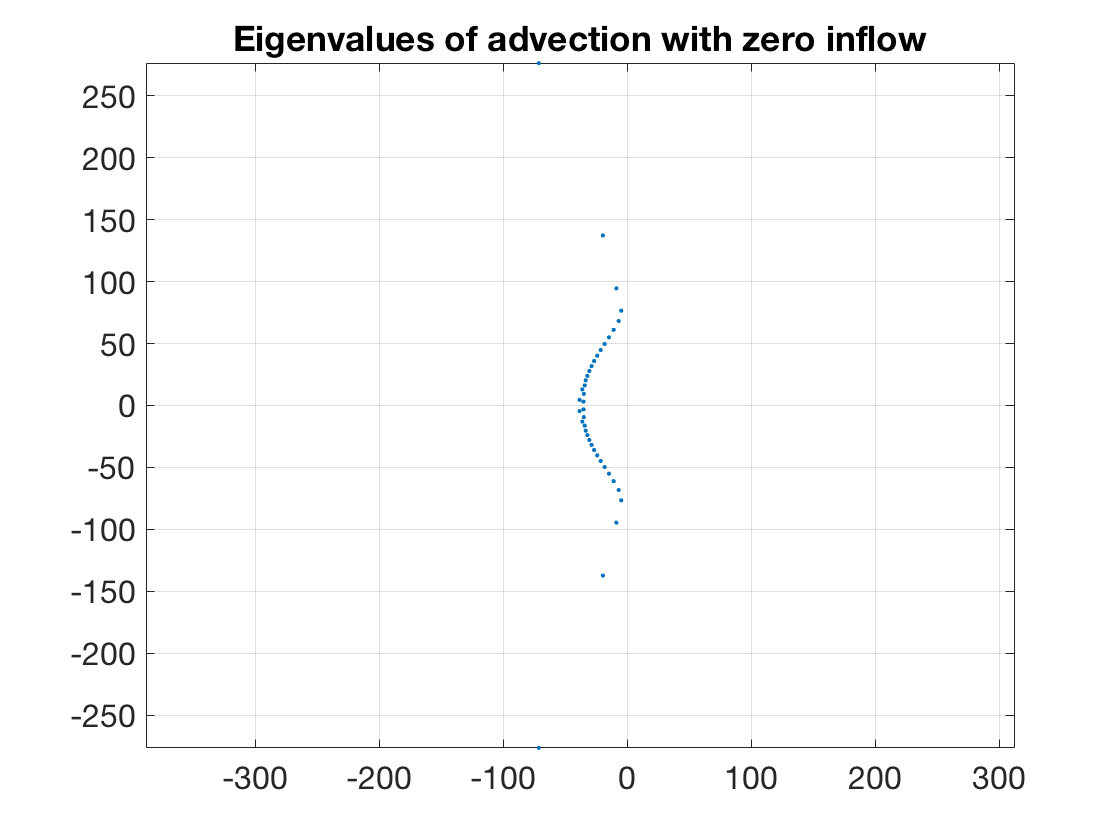

[x,Dx,Dxx] = diffcheb(40,[0,1]);
A = -Dx(2:end,2:end);    % leave out first row and column
lambda = eig(A);
plot(real(lambda),imag(lambda),'.')
axis equal,  grid on     % ignore this line
title('Eigenvalues of advection with zero inflow')    % ignore this line

Note that the rightmost eigenvalues have real part at most

max( real(lambda) )

ans = -4.9320

Consequently all solutions decay exponentially to zero as $t\to\infty$. This matches the intuition of a flow with nothing at the inlet: eventually everything flows out of the domain. 